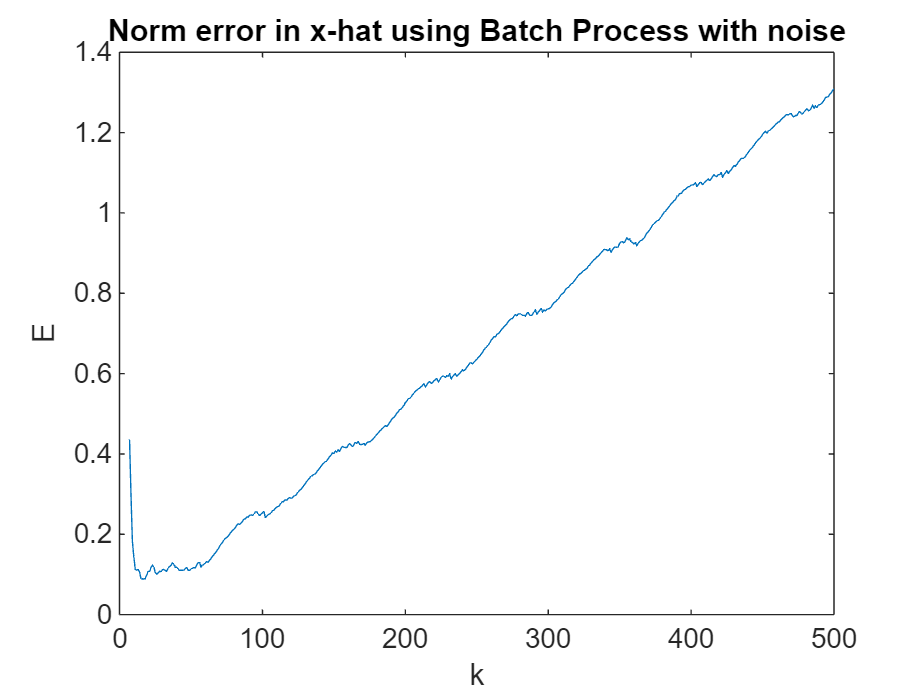

%HW 7 Q5a
tic
close all
clear 
clc
load("DataHW07_Prob5.mat")
temp = cell2mat(C(1));
temp_1 = size(temp);
n = ceil(temp_1(2)/temp_1(1));
for i = 1:n-1
    if (i == 1)
        Ak = cell2mat(C(i));
        Yk = cell2mat(y(i));
    else
        Ak = [Ak;cell2mat(C(i))];
        Yk = [Yk;cell2mat(y(i))];
    end
end

for k = n:N
    Ak = [Ak;cell2mat(C(k))];
    Yk = [Yk;cell2mat(y(k))];
    Rk = eye(3*k);
    xk_hat = inv(Ak'*Rk*Ak) * (Ak'*Rk*Yk);
    Ek_temp = xk_hat - cell2mat(x_actual(k));
    Ek_temp1 = Ek_temp.^2;
    if (k == n)
    Ek = sum(Ek_temp1)^0.5;
    else
    Ek = [Ek;(sum(Ek_temp1))^0.5];
    end
end
plot(n:N,Ek)
title('Norm error in x-hat using Batch Process with noise')
xlabel('k')
ylabel('E')

toc

Elapsed time is 1.094195 seconds.
